# Lab Assignment 1: Solving Systems of Linear Equations Describing Electrical Circuits

**Your full name:**   Gaurika Mahajan

**Your utorID:**      mahaj133

## A more complex circuit

Consider the following circuit with a variable resistor $R_L$:

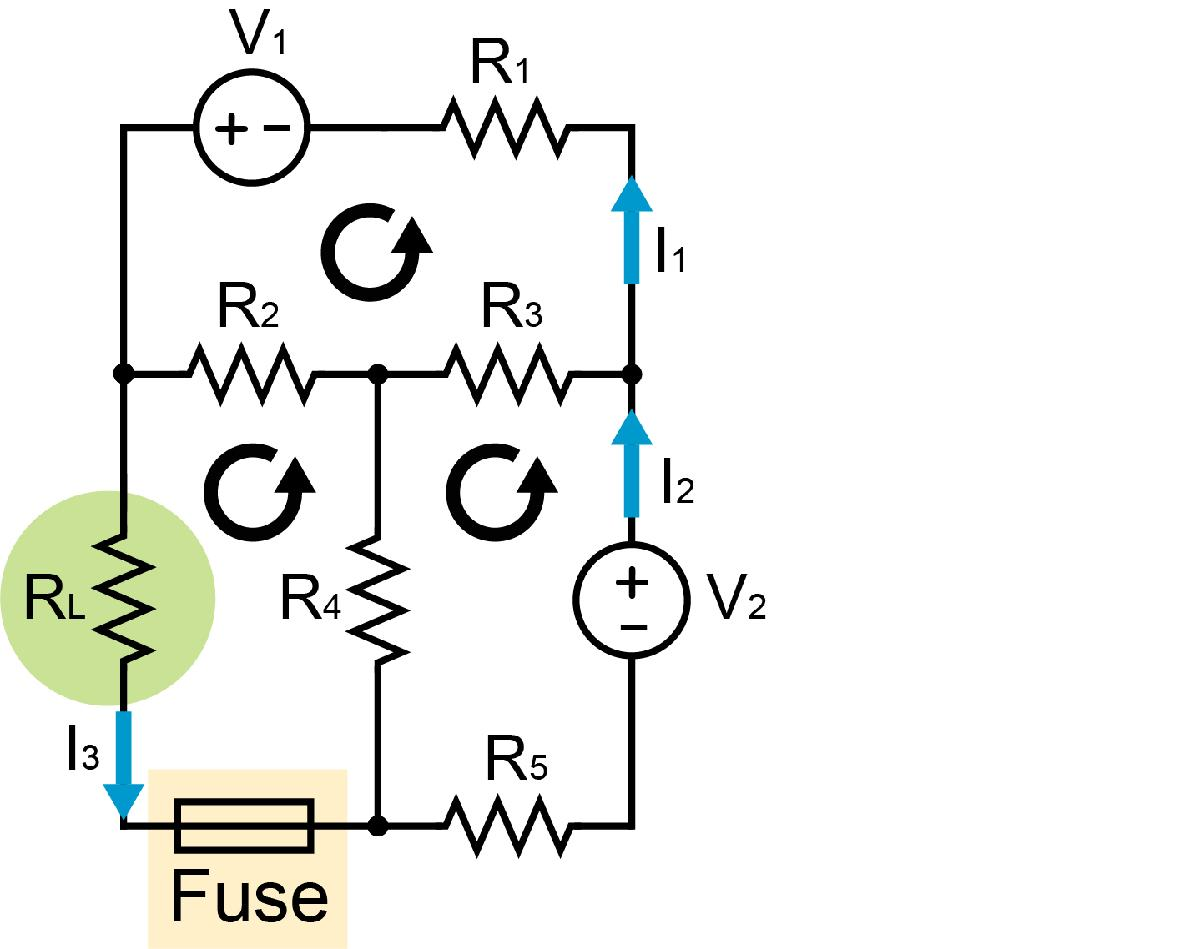

We can construct a system of equations to describe this circuit using a combination of KVL and KCL:

*        top loop: *$V_1 -R_2 \left(I_1 -I_3 \right)+R_{3\;} \left(I_2 -I_1 \right)-R_1 I_1 =0$

*        left loop:* ${-R}_L I_{3\;} -R_4 \left(I_3 -I_{2\;} \right)+R_{2\;} \left(I_{1\;} -I_3 \right)=0$

*        outmost loop: *$V_1 -R_L I_3 -R_5 I_{2\;} +V_2 -R_1 I_1 =0$ 

## Problem 1: Finding the minimum resistance to keep the fuse intact

The fixed circuit parameters are defined here for you.

    Resistors: 

R1 = 8; R2 = 4; R3 = 4; R4 = 6; R5 = 1;  % Units: Ohms

    Voltage sources: 

V1 = 120; V2 = 120; % Units: Volts

**What must the variable resistor (**$R_L$**) be set to in order to prevent a 5 Amp fuse from melting?**

- Tell MATLAB to display the value for $R_L$ to 1 decimal place using fprintf and matrix indexing.  

- eg. you should be getting this value directly from a variable in memory

Hint: Include the unknown resistance as a variable in your system of equations.

            eg.  $x=\left\lbrack \begin{array}{c}
I_1 \\
I_2 \\
R_L 
\end{array}\right\rbrack$

%%% enter your code below %%%
I3 = 5;
M = [-R2-R1-R3, R3, 0;
    R2, R4, -I3;
    -R1,-R5,-I3;];
b = [-V1-(R2*I3); (R4*I3) + (R2*I3); -V2-V1;];
x = [linsolve(M,b)];    %solving the matrix
R_L = x(3,1);           %defining the R_L value from the solved matrix
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
final_answer = x(3,1);   %%% ← complete this line %%%
fprintf('The minimum R_L to prevent melting the fuse is %.1f Ohms.', final_answer)

The minimum R_L to prevent melting the fuse is 22.9 Ohms.

## Problem 2: Using a for loop to approximate the answer

In many real life scenarios, an numerical estimate is often adequate for most engineering applications, especially because it may not be feasible to compute an exact solution.

**Use a for-loop to solve this circuit for varying values of **$R_L$** to find the resitance in **$R_L$** that will lead to excessive current through the fuse.**

- Test values of $R_L$ between 0 and 50 Ohms, in steps of 0.5 Ohms

- Save the resultant current that would be going through the fuse

- Print the value of $R_L$ that will cause the 5 Amp fuse to melt

Hints:

- In this part, we need to reconstruct our system of equations. 

- Now, our unknowns will be $I_1 ,I_{2\;}$, and $I_3$. We compute the value of $I_3$ given a some value for $R_L$.

resistanceVariable = [];                %defining empty vector for storing RL values
I3_vecValues = [];                      %defining empty vector for storing I3 values
resistanceMeltedValues = [];            %defining empty vector for storing RL values that melt the fuse
for x = 0:0.5:50
    R_L = x;
    resistanceVariable(end + 1) = R_L;
    M = [-R2-R1-R3, R3, R2;
    R2, R4, -R_L-R4-R2;
    -R1,-R5,-R_L;];
    b = [-V1; 0; -V2-V1;];
    solvedMatrix = [linsolve(M,b)];     %solving the matrix 
    I3 = solvedMatrix(3,1);             %defining I3 from the solved matrix
    I3_vecValues(end+1) = I3;           %adding the I3 value to the empty I3 vector 
    if I3>5                             %condition for when I3 melts
        RLMelted = R_L;                 %defining what resistance value melts the fuse
        resistanceMeltedValues(end+1) = RLMelted;
    end
    if R_L == RLMelted + 0.5            %determining what the maximum I3 value is before the fuse melts 
        maxI3Value = I3;
    end
end
meltValue = max(resistanceMeltedValues);
fprintf('The maximum R_L that causes the fuse to melt is %.1f Ohms', meltValue)

The maximum R_L that causes the fuse to melt is 22.5 Ohms

**Generate a scatter plot of your simulation:**

- Show the variable resistance on the x-axis and the resultant current through the fuse on the y-axis

- Include a horizontal line indicating the maximum current of the fuse

- Remember to label your plot axes and add a plot title

Hint: The following commands may be useful.

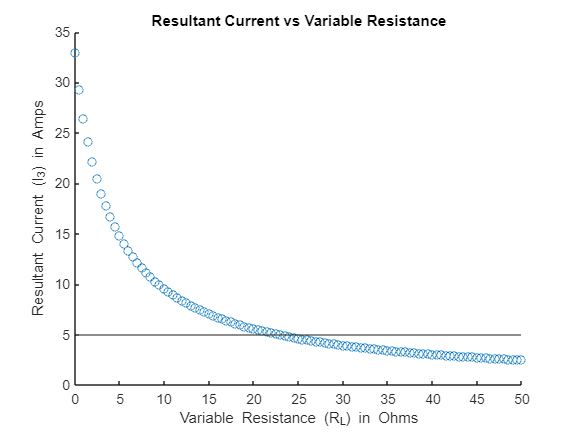

scatter(resistanceVariable, I3_vecValues);          %scatter plotting the current vs resistance 
xlabel('Variable Resistance (R_L) in Ohms')         %labelling x axis
ylabel('Resultant Current (I_3) in Amps')           %labelling y axis
title('Resultant Current vs Variable Resistance')   %title for graph
yline(maxI3Value)                                   %horizontal line for the max current of fuse before it reaches 5 amps

## Problem 3: Simulating the current through $I_2$ as the fuse melts

When a fuse melts, it completely interrupts the flow of current through the circuit at that point.

Imagine an experimenter set-up this circuit in the lab, with the variable resistor ($R_L$) initially set to 50 Ohms, and a fuse that will melt above 5 Amps. The experimenter gradually reduce the resistance in the resistor until it reaches 0 Ohms. **Plot the current **$I_2$** against the resistance in **$R_L$ **as the resistor is adjusted from 50 Ohms down to 0 Ohms.**

Hints: 

- Start by copying the for-loop you wrote for Problem 2B above.

- You may need to solve the circuit twice in the for-loop: once to determine if the fuse will melt, and once again to solve the circuit accounting for if the fuse is melted.

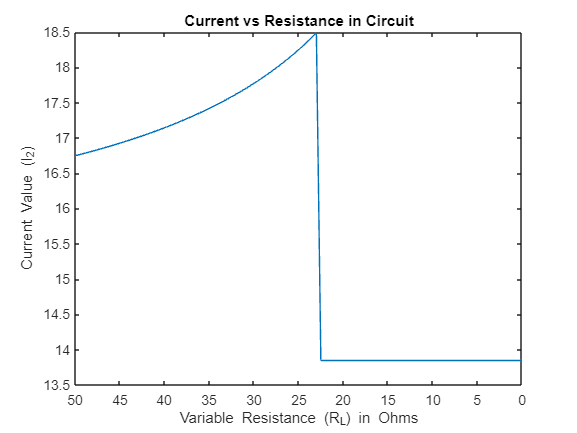

resistance2 =[];                %defining empty vector for storing R_L values for problem 3
currentTwoValues = [];          %defining empty vector for storing I2 values
for x = 50:-0.5:0               %descending R_L values
    R_L = x;
    resistance2(end + 1) = R_L;
    M = [-R2-R1-R3, R3, R2;
          R2, R4, -R_L-R4-R2;
         -R1,-R5,-R_L;];
    b = [-V1; 0; -V2-V1;];
    solvedMatrix = [linsolve(M,b)];    %solving the matrix 
    I2 = solvedMatrix(2);
    I3 = solvedMatrix(3,1);
    if I3 < 5
        currentTwoValues(end + 1) = I2;
    elseif I3 > 5                %the fuse has melted, must recalculate I2
        A = [-R2+R3-R1, -R3;     %redefining the matrix by accounting for fuse melting
            R3, -R4-R3-R5;];
        c = [-V1; -V2;];
        solvedMeltedMatrix = [linsolve(A,c)];   %solving new matrix for I2
        I2 = solvedMeltedMatrix(2,1);
        currentTwoValues(end + 1) = I2;         %adding I2 into the I2 vector
    end
end
plot(resistance2, currentTwoValues);             %creating the graph that plots current vs resistance
set(gca, 'xdir', 'reverse' )                    %reversing the direction of x axis
xlabel('Variable Resistance (R_L) in Ohms')     %labelling x axis
ylabel('Current Value (I_2)')                   %labelling y axis
title('Current vs Resistance in Circuit')       %title for graph